## Map TSA per day

Load 3d array of TSA

Contains: 

** arr_tsa**: 3d matrix of integers based of TSA applied ϴ=[0.30, 1.53, 2.40, 3.00, 3.55]  

**arr_date**: vector of date of images MODIS/NDVI

**study_area**: binary matrix of the study area. 0 indicates a pixel outside study area and 1 a pixel inside. 

load("arr_ndvi_3d.mat");
load ("arr_tsa_3d.mat");

%% others vars

% affected zone 
lat_map = [22.8652674518157	23.4968502726837];
lon_map=[-99.4678284807873	-99.0517640714205];


colmap_nbr = [
    0.47 0.53 0.20
    0.65 0.75 0.31
    0.05 0.90 0.27
    0.97 0.98 0.06
    0.97 0.70 0.25
    0.97 0.40 0.10
    0.65 0.00 0.83
    ];

altndvimap = {'#D73027','#F46D43','#FDAE61','#FEE08B','#FFFFBF','#D9EF8B','#A6D96A','#66BD63','#1A9850','#006837'};
ndvi_altcolormap = validatecolor(altndvimap, 'multiple');

%% Select the day you can see
% 511 before forestfire March 6, 2022
% 516 May 25, 2022
% 518 June 25, 2022

id_day = 516;
tsa_map = arr_tsa(:,:,id_day);


## Adjust TSA index to NBR index for correct colormap

mapa_tsa_nbr = zeros(size(tsa_map));
    
mapa_tsa_nbr(tsa_map==-5)=-4;
mapa_tsa_nbr(tsa_map==-4)=-3;
mapa_tsa_nbr(tsa_map==-3)=-2;
mapa_tsa_nbr(tsa_map==-2)=-1;
mapa_tsa_nbr(tsa_map==-1)=0;
mapa_tsa_nbr(tsa_map==0 | tsa_map==1)=1;
mapa_tsa_nbr(tsa_map>=2)=2;
mapa_tsa_nbr(study_area==0)=nan;

% Calculate NDVI for the id_day

ndvi_day = double(arr_ndvi_jdasa(:,:,id_day));
ndvi_day=ndvi_day.*0.0001;
ndvi_day(study_area==false)=nan;

## draw map

using m_map library

We use m_map to generate the maps istalled from: 

[https://www-eoas-ubc-ca.translate.goog/~rich/map.html?_x_tr_sl=en&_x_tr_tl=es&_x_tr_hl=es&_x_tr_pto=tc](https://www-eoas-ubc-ca.translate.goog/~rich/map.html?_x_tr_sl=en&_x_tr_tl=es&_x_tr_hl=es&_x_tr_pto=tc)

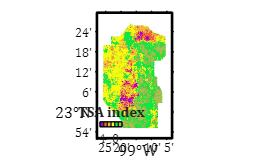

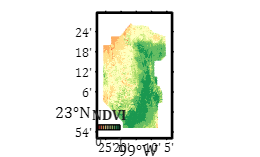

%if exist('m_proj','file')~=0
    % TSA NBR
    figure;
    m_proj('mercator','lon',lon_map,'lat',lat_map);
    m_pcolor(lon,lat,mapa_tsa_nbr); shading interp ;
    m_grid('linestyle','none','box','fancy','tickdir','out','fontsize',10,'FontName','Cambria');
    colormap(flipud(colmap_nbr));
    [ax,~]=m_contfbar([0.33 0.44],0.12,[0 1],-4:1:2,'endpiece','no','axfrac',.04,'FontName','Cambria');
    title(ax,"TSA index");



    %NDVI
    figure;
    m_proj('mercator','lon',lon_map,'lat',lat_map);
    colormap(ndvi_altcolormap);
    m_pcolor(lon,lat,ndvi_day); shading interp ;
    m_grid('linestyle','none','box','fancy','tickdir','out','fontsize',10,'FontName','Cambria');
    [ax,~]=m_contfbar([0.32 0.43],0.1,[0 1],0:0.1:1,'endpiece','no','axfrac',.04,'FontName','Cambria');
    title(ax,'NDVI');
%else

Using pcolorm

Approximate map using pcolorm if you don't have m_map

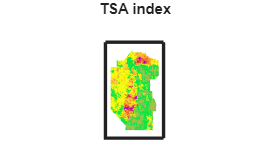

    % TSA NBR
    figure;
    ax = axesm('MapProjection','mercator','MapLatLimit',lat_map,'MapLonLimit',lon_map,'Frame','on','Grid','on');
    axis off; framem on; gridm on;
    colormap(flipud(colmap_nbr));
    pcolorm(lat,lon,mapa_tsa_nbr); %shading interp;
    title("TSA index");
    setm(gca,'MeridianLabel','on','ParallelLabel','on','MLineLocation',5,'PLineLocation',5,'MLabelLocation',5,'PLabelLocation',5)

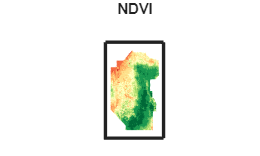

    
    % NDVI
    figure;
    ax = axesm('MapProjection','mercator','MapLatLimit',lat_map,'MapLonLimit',lon_map,'Frame','on','Grid','on');
    axis off; framem on; gridm on;
    colormap(ndvi_altcolormap);
    pcolorm(lat,lon,ndvi_day); %shading interp;
    % 4. Show and customize Latitude/Longitude Labels
    title("NDVI");

%end